# Chapter 4, Section 1 (Part 1)

The goal of this activity is to introduce what is known as a linear transformation. Let's start with the definition.

**Definition: **Let $V$ and $W$ be vector spaces. The mapping $T:\ V\rightarrow W$ is called a **linear transformation** if an only if


$$T(\vec u+\vec v)=T(\vec u)+T(\vec v)\qquad\text{and}\qquad T(c\vec u)=cT(\vec u)$$


for all $\vec u, \vec v\in V$ and all $c\in R$. If $T: V\rightarrow V$, then $T$ is called a **linear operator**. For each $\vec u\in V$, the vector $\vec w=T(\vec u)$ is called the **image **of $\vec u$ under $T$.

Let's do some examples.

# Example #1

Define $T:R^2\rightarrow R^2$ by $T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr 3x-y}$. Determine if $T$ is a linear transformation.

**Solution:** We need to show two things:

- $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ for all $\vec u, \vec v\in R^2$.

- $T(c\vec u)=cT(\vec u)$ for all $\vec u\in R^2$ and $c\in R$.

**Part 1: ** Let $\vec u=\pmatrix{x_1\cr y_1}$ and $\vec v=\pmatrix{x_2\cr y_2}$ be vectors in $\mathbb R^2$. Then we can write:


$$\begin{array}{rcl}{
T(\vec u+\vec v)&=&T\left(\pmatrix{x_1\cr y_1}+\pmatrix{x_2\cr y_2}\right)\\
&=&T\left(\pmatrix{x_1+x_2\cr y_1+y_2}\right)
\end{array}
$$


Now we can substitute $x_1+x_2$ for $x$ and $y_1+y_2$ for $y$ in the formula $T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr 3x-y}$ and continue with:


$$\begin{array}{rcl}{
T(\vec u+\vec v)&=&\pmatrix{(x_1+x_2)+2(y_1+y_2)\cr 3(x_1+x_2)-(y_1+y_2)}\\
&=&\pmatrix{x_1+x_2+2y_1+2y_2\cr 3x_1+3x_2-y_1-y_2}\\
&=&\pmatrix{(x_1+2y_1)+(x_2+2y_2)\cr (3x_1-y_1)+(3x_2-y_2)}\\
&=&\pmatrix{x_1+2y_1\cr 3x_1-y_1}+\pmatrix{x_2+2y_2\cr 3x_2-y_2}\\
&=&T\left(\pmatrix{x_1\cr y_1}\right)+T\left(\pmatrix{x_2\cr y_2}\right)\\
&=&T(\vec u_1)+T(\vec v_1)
\end{array}
$$


**Part 2: **Let $\vec u=\pmatrix{x_1\cr y_1}$ and $c\in R$. Then we can write:


$$\begin{array}{rcl}
T(c\vec u)&=&T\left(c\pmatrix{x_1\cr y_1}\right)\\
&=&T\left(\pmatrix{cx_1\cr cy_1}\right)
\end{array}$$


Now we can substitute $cx_1$ for $x$ and $cy_1$ for $y$ in the formula $T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr 3x-y}$ and continue with:


$$\begin{array}{rcl}
T(c\vec u)&=&\pmatrix{cx_1+2cy_1\cr 3cx_1-cy_1}\\
&=&c\pmatrix{x_2+2y_1\cr 3x_1- y_1}\\
&=&cT\left(\pmatrix{x_1\cr y_1}\right)\\
&=&T(c\vec u)
\end{array}$$


Because we have shown that $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ and $T(c\vec u)=cT(\vec u)$, $T$ is a linear transformation.

# Why is it Called a Linear Transformation?

We know how to find the equation of a line that passes through the point $(2,3)$ with slope $-3/2$.


$$\begin{array}{rcl}
y-y_0&=&m(x-x_0)\\
y-3&=&-\frac32(x-2)\\
y-3&=&-\frac32x+3\\
y&=&-\frac32x+6
\end{array}$$


And we can sketch this line in Matlab.

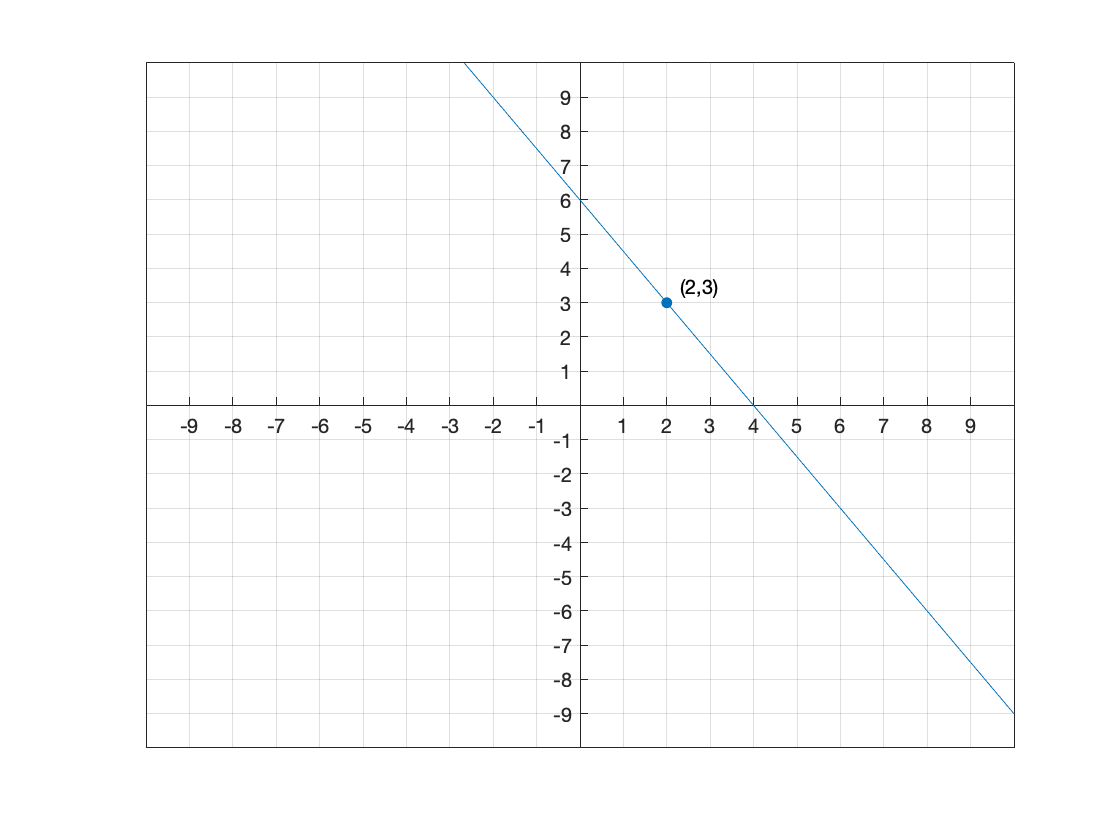

x=-10:10;
y=-3/2*x+6;
plot(x,y)
line(2,3,'Marker','.','MarkerSize',16)
grid on
axis([-10,10,-10,10])
xticks(-10:10)
yticks(-10:10)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2.3,3.5,'(2,3)')

Now, let's recall the parallelogram method for adding two vectors.

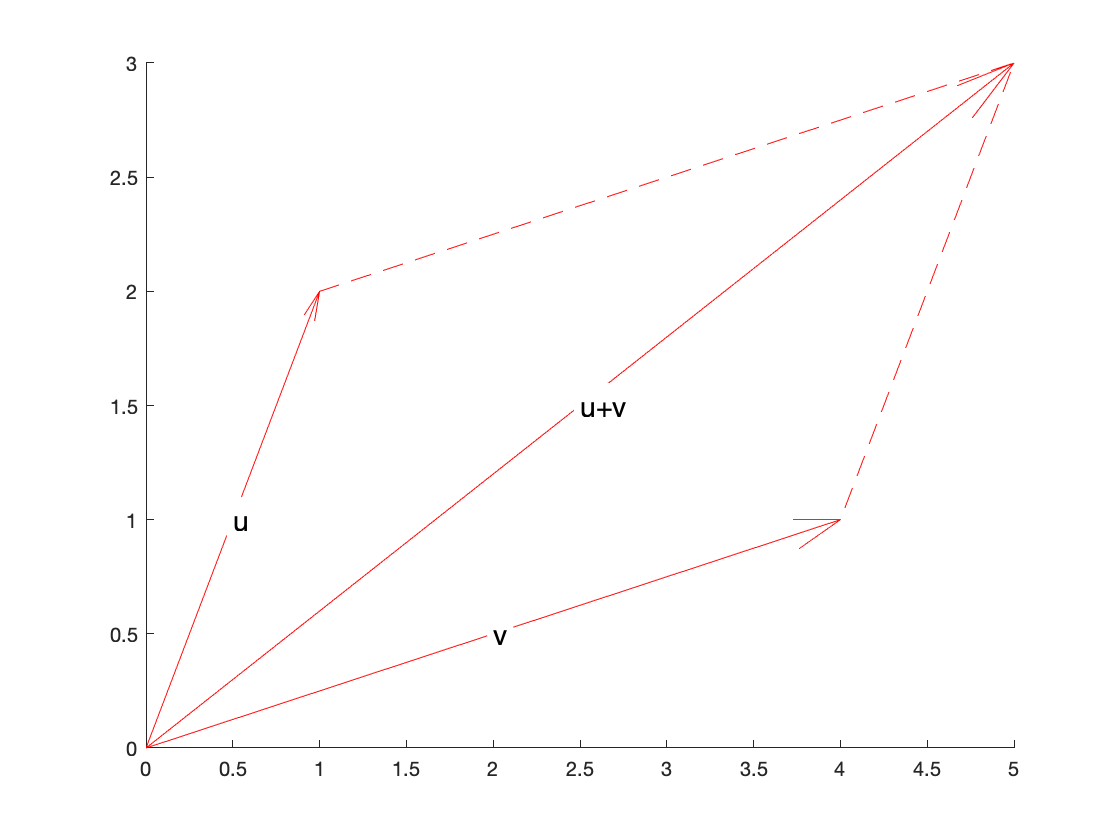

figure, hold on
quiver(0,0,1,2,0,'r')
quiver(0,0,5,3,0,'r')
quiver(0,0,4,1,0,'r')
line([1,5,4],[2,3,1],'LineStyle','--','Color','r')
text(0.5,1,'u','BackgroundColor','w','FontSize',14)
text(2.5,1.5,'u+v','BackgroundColor','w','FontSize',14)
text(2,0.5,1,'v','BackgroundColor','w','FontSize',14)
hold off

Note that the sides of the parallelogram are parallel and the same length, so another way of adding two vectors $\vec u$ and $\vec v$ geometrically is to add the beginning of vector $\vec v$ to the tip of vector $\vec u$, then draw the vector $\vec u+\vec v$ by beginning at the base of $\vec u$ and ending at tip of vector $\vec v$.

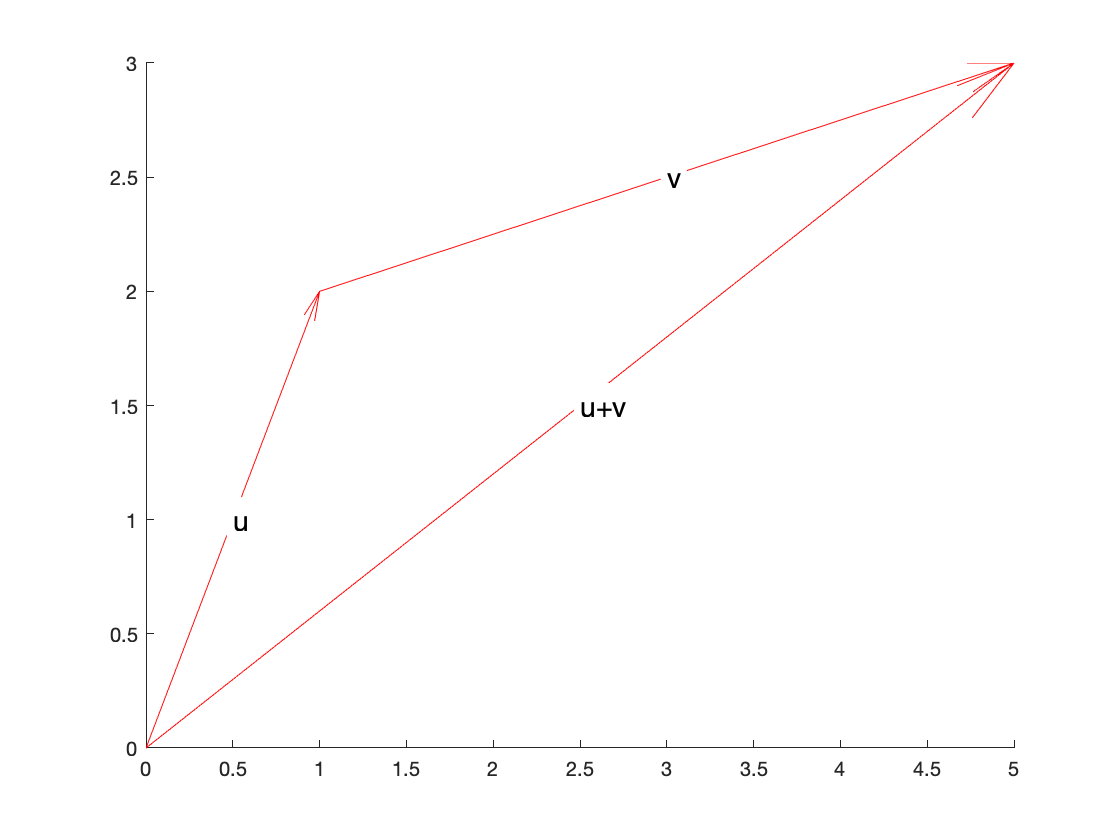

figure, hold on
quiver(0,0,1,2,0,'r')
quiver(0,0,5,3,0,'r')
quiver(1,2,4,1,0,'r')
text(0.5,1,'u','BackgroundColor','w','FontSize',14)
text(2.5,1.5,'u+v','BackgroundColor','w','FontSize',14)
text(3,2.5,1,'v','BackgroundColor','w','FontSize',14)
hold off

We will find this extremely useful. Now, let's draw our line $y=(-3/2)x+6$ again, but this time add some vectors to our image.

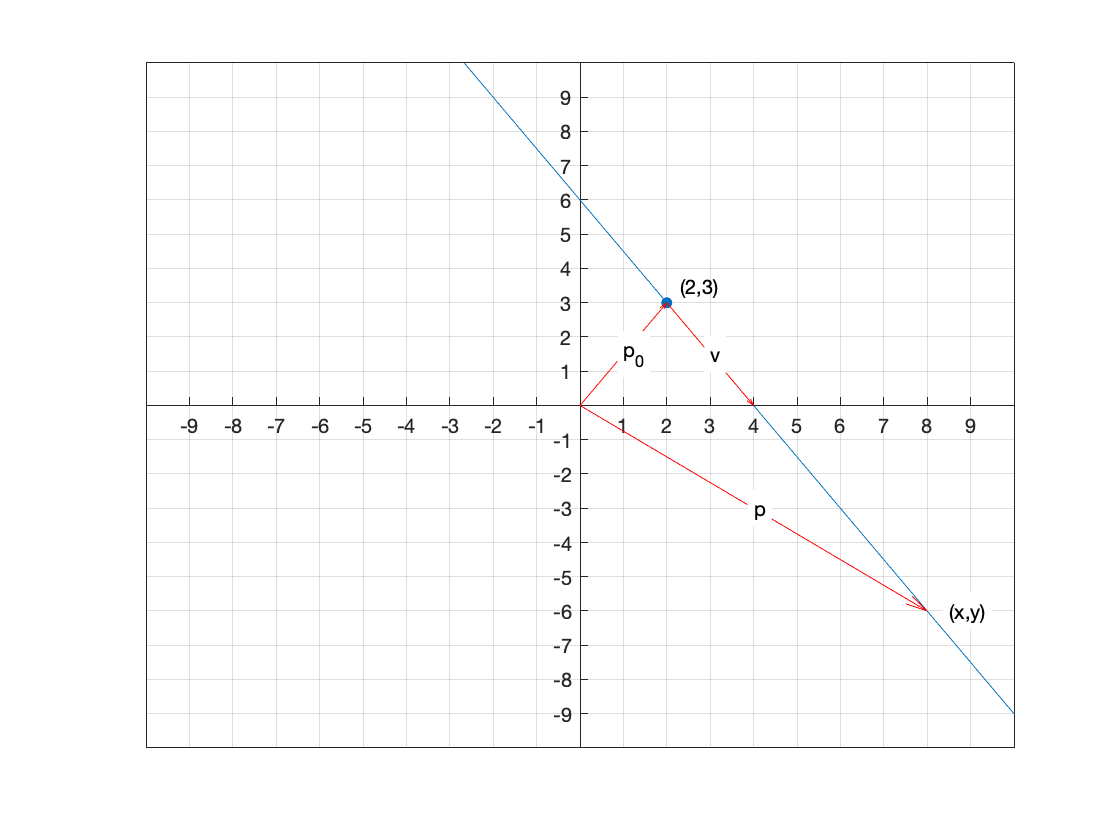

x=-10:10;
y=-3/2*x+6;
plot(x,y)
line(2,3,'Marker','.','MarkerSize',16), hold on
quiver(0,0,2,3,0,'r')
quiver(2,3,2,-3,0,'r')
quiver(0,0,8,-6,0,'r')
grid on
axis([-10,10,-10,10])
xticks(-10:10)
yticks(-10:10)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2.3,3.5,'(2,3)')
text(8.5,-6,'(x,y)','BackgroundColor','w')
text(3,1.5,'v','BackgroundColor','w')
text(1,1.5,'p_0','BackgroundColor','w')
text(4,-3,'p','BackgroundColor','w')
hold off

Using our new method for adding two vectors above, note that the vector $\vec p$,  whose tip lies on our line, is the sum of $\vec p_0$ and some scalar multiple $t$ of $\vec v$. That is, the equation of the line is:


$$\vec p=\vec p_0+t\vec v$$


Examining our image, $\vec p_0=\pmatrix{2\cr 3}$, $\vec v=\pmatrix{2\cr -3}$, and $\vec p=\pmatrix{x\cr y}$. Substituting these into our equation gives us:


$$\begin{array}{rcl}
\pmatrix{x\cr y}&=&\pmatrix{2\cr 3}+t\pmatrix{2\cr -3}\\
\pmatrix{x\cr y}&=&\pmatrix{2+2t\cr 3-3t}
\end{array}$$


This is the equation of our line. Now, do we trust this? Let's sketch this and see if we get the same result. Note that:


$$\begin{array}{rc}
x&=&2+2t\\
y&=&3-3t
\end{array}$$


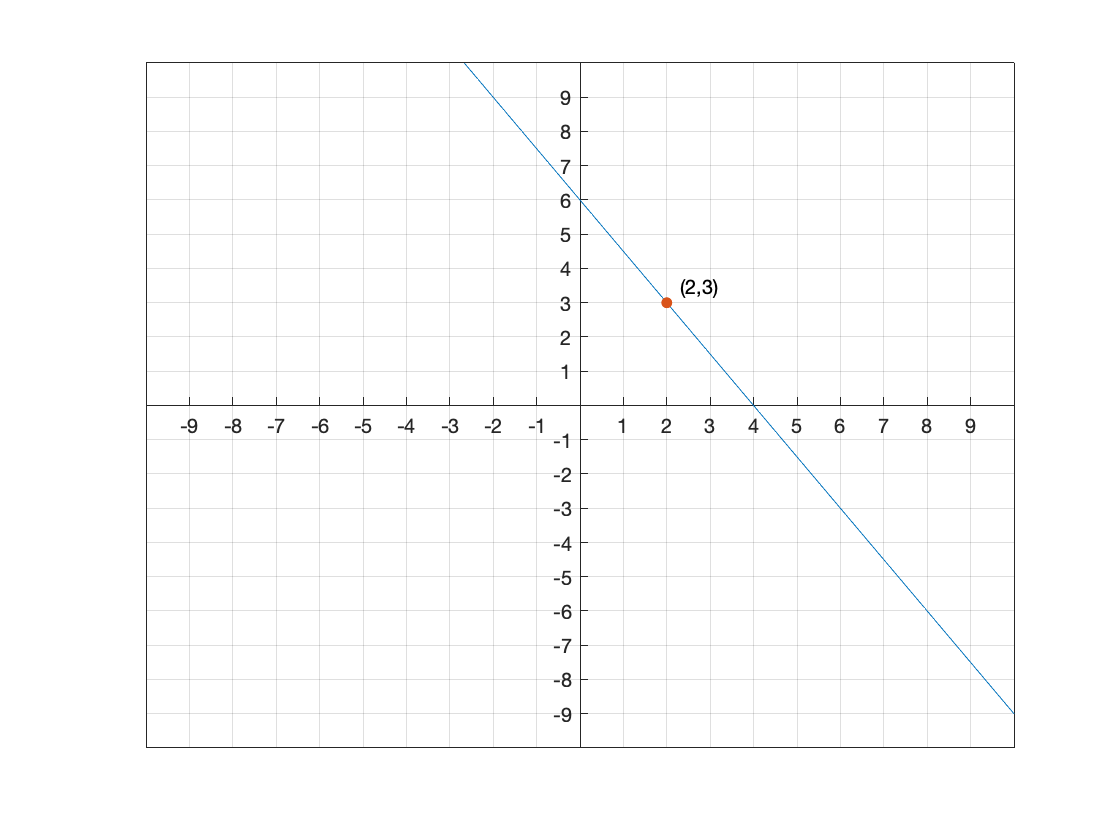

t=linspace(-5,5);
x=2+2*t;
y=3-3*t;
plot(x,y),hold on
plot(2,3,'Marker','.','MarkerSize',16)
grid on
axis([-10,10,-10,10])
xticks(-10:10)
yticks(-10:10)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2.3,3.5,'(2,3)')
hold off

Same line! Now why is $T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr 3x-2y}$ called a linear transformation? Let's see what $T$ does when we apply it to our line. Recall that the equation of our line is:


$$\begin{array}{rcl}
x&=&2+2t\\
y&=&3-3t
\end{array}$$


Let's transform our line by substituting these into $T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr 3x-2y}$.


$$\begin{array}{rcl}
T\left(\pmatrix{2+2t\cr 3-3t}\right)&=&\pmatrix{(2+2t)+2(3-3t)\cr 3(2+2t)-2(3-3t)}\\
&=&\pmatrix{8-4t\cr 12t}
\end{array}$$


Now, let's add this result to our image.

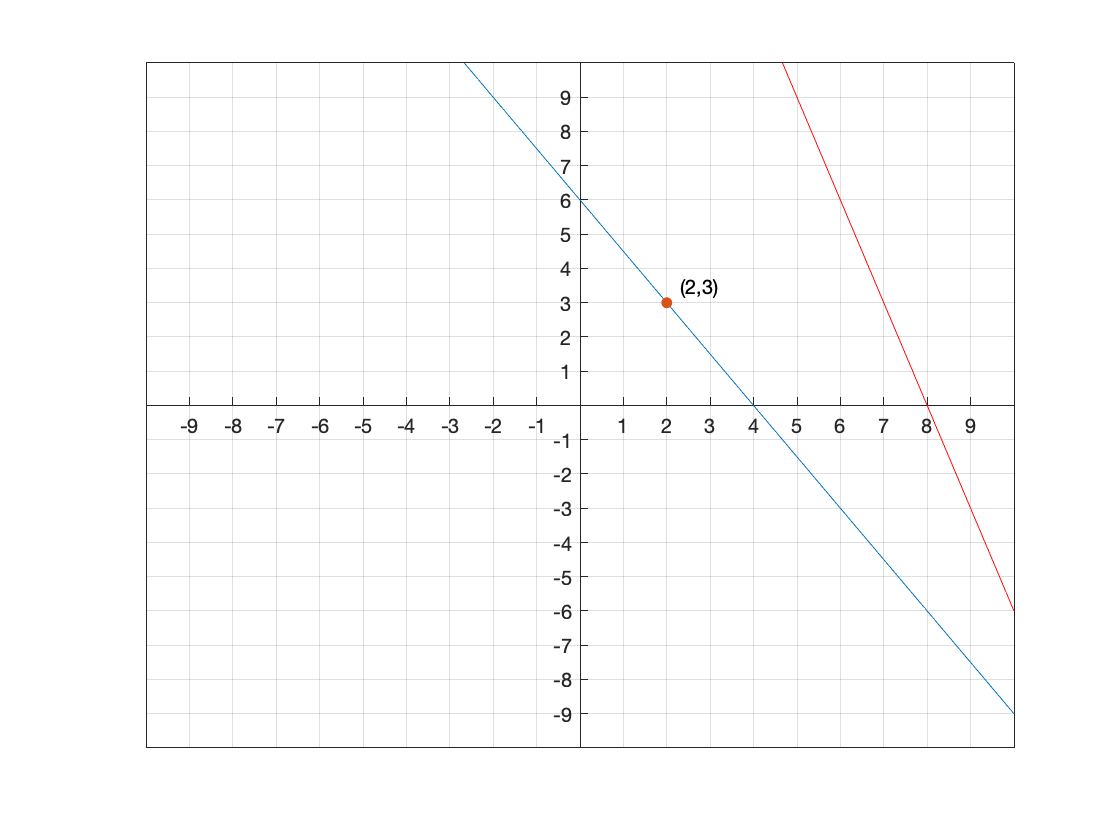

t=linspace(-5,5);
x=2+2*t;
y=3-3*t;
plot(x,y),hold on
plot(2,3,'Marker','.','MarkerSize',16)
u=8-4*t;
v=12*t;
plot(u,v,'r')
grid on
axis([-10,10,-10,10])
xticks(-10:10)
yticks(-10:10)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2.3,3.5,'(2,3)')
hold off

It's a line!

**Caution:** In our next section we will see that some linear transformations will transform a line to a single point.

# Example #2

Define $T:R^2\rightarrow R^2$ by $T\left(\pmatrix{x\cr y}\right)=\pmatrix{2x^2\cr -y}$. Determine if $T$ is a linear transformation.

**Solution:** We need to show two things:

- $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ for all $\vec u, \vec v\in R^2$.

- $T(c\vec u)=cT(\vec u)$ for all $\vec u\in R^2$ and $c\in R$.

**Part 1: **Let $\vec u=\pmatrix{x_1\cr y_1}$ and $\vec v=\pmatrix{x_2\cr y_2}$. Then we can write:


$$\begin{array}{rcl}{
T(\vec u+\vec v)&=&T\left(\pmatrix{x_1\cr y_1}+\pmatrix{x_2\cr y_2}\right)\\
&=&T\left(\pmatrix{x_1+x_2\cr y_1+y_2}\right)
\end{array}
$$


Now we can substitute $x_1+x_2$ for $x$ and $y_1+y_2$ for $y$ in the formula $T\left(\pmatrix{x\cr y}\right)=\pmatrix{2x^2\cr -y}$ and continue with:


$$\begin{array}{rcl}{
T(\vec u+\vec v)&=&\pmatrix{2(x_1+x_2)^2\cr -(y_1+y_2)}\\&=&\pmatrix{2x_1^2+4x_1x_2+2x_2^2\cr -y_1-y_}
\end{array}
$$


We're not sure how to proceed, so let's calculate $T(\vec u)+T(\vec v)$ and see if we get the same answer.


$$\begin{array}{rcl}
T(\vec u)+T(\vec v)&=&T\left(\pmatrix{x_1\cr y_1}\right)+T\left(\pmatrix{x_2\cr y_2}\right)\\
&=&\pmatrix{2x_1^2\cr -y_1}+\pmatrix{2x_2^2\cr -y_2}\\
&=&\pmatrix{2x_1^2+2x_2^2\cr -y_1-y_2}
\end{array}$$


We've shown that $T(\vec u+\vec v)\ne T(\vec u)+T(\vec v)$, so we've shown that $T$ is **not** a linear transformation, so there is no need to go on to Part 2. We're done.

Now, why is this a not a linear transformation? Let's see what it does to our line in Example #1. Recall that the equation of the line was:


$$\begin{array}{rcl}
x&=&2+2t\\
y&=&3-3t
\end{array}$$


Let's substitute this into our nonlinear transformation $T\left(\pmatrix{x\cr y}\right)=\pmatrix{2x^2\cr -y}$.


$$\begin{array}{rcl}
T\left(\pmatrix{2+2t\cr 3-3t}\right)&=&\pmatrix{2(2+2t)^2\cr -(3-3t)}\\
&=&\pmatrix{8+8t+8t^2\cr -3+3t}
\end{array}$$


Let's add this to our line image in Example #1.

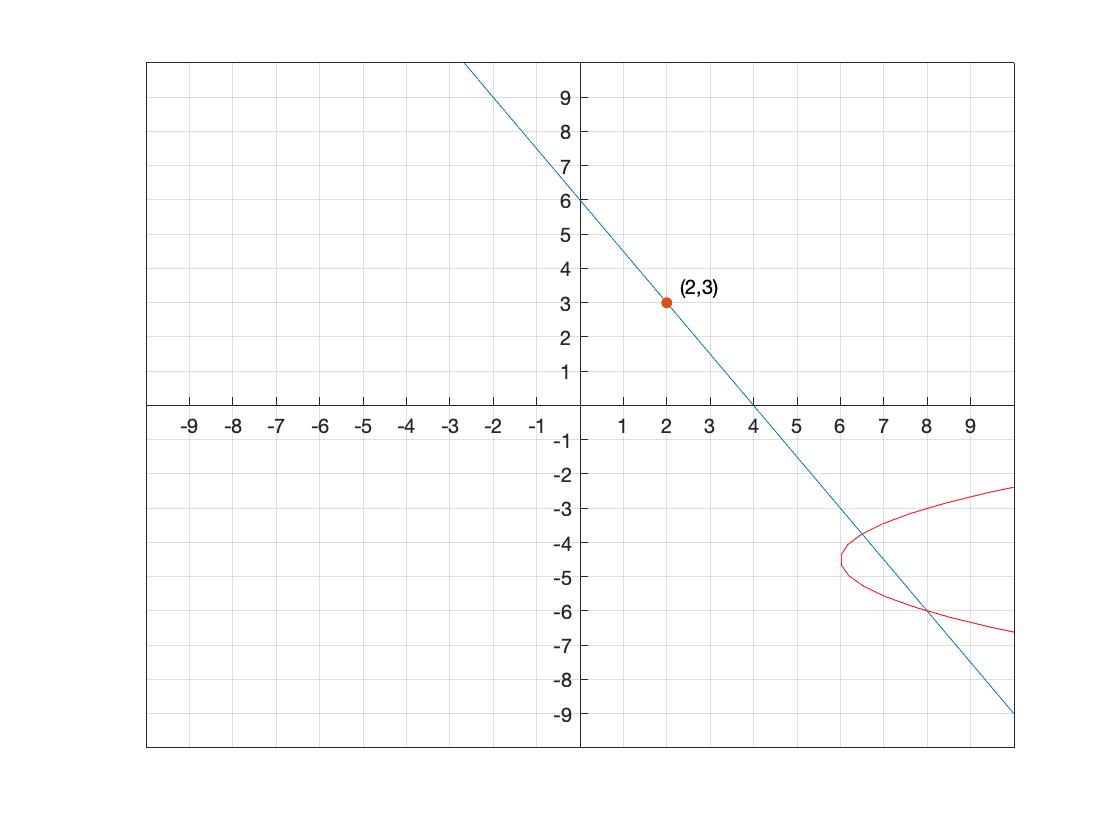

t=linspace(-5,5);
x=2+2*t;
y=3-3*t;
plot(x,y),hold on
plot(2,3,'Marker','.','MarkerSize',16)
u=8+8*t+8*t.^2;
v=-3+3*t;
plot(u,v,'r')
grid on
axis([-10,10,-10,10])
xticks(-10:10)
yticks(-10:10)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2.3,3.5,'(2,3)')
hold off

It's not a line. :-(

# Example #3

Let $A$ be an $m\times n$ matrix. Define a mapping $T: R^n\rightarrow R^m$ by  $T(\vec x)=A\vec x$.

**Part a): **Show that $T$ is a linear transformation.

**Part b): **Let $A=\pmatrix{1 & -1 & -2\cr 2 & 1 & 2}$. Find the image of $\vec u=\pmatrix{1\cr 2\cr 5}$ under the mapping $T: R^3\rightarrow R^2$ with $T(\vec x)=A\vec x$.

**Solution:** 

**Part a: **We need to show two things:

- $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ for all $\vec u, \vec v\in R^n$.

- $T(c\vec u)=cT(\vec u)$ for all $\vec u\in R^n$ and $c\in R$.

**Part 1: **Let $\vec u, \vec v\in R^n$. Then we can write:


$$\begin{array}{rcl}
T(\vec u+\vec v)&=&A(\vec u+\vec v)\\
&=&A\vec u+A\vec v\\
&=&T(\vec u)+T(\vec v)
\end{array}$$


**Part 2: **Let $\vec u\in R^n$ and $c\in R$. Then we can write:


$$\begin{array}{rcl}
T(c\vec u)&=&A(c\vec u)\\
&=&c\,(A\vec u)\\
&=&c\,T(\vec u)
\end{array}$$


We've proved that $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ and $T(c\vec u)=cT(\vec u)$, so $T$ is a linear transformation.

**Important Note: **Consider the linear transformation in Example #1, $T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr 3x-y}$. Note that we can manipulate this as follows:


$$\begin{array}{rcl}
T\left(\pmatrix{x\cr y}\right)&=&\pmatrix{x+2y\cr 3x-y}\\
&=&\pmatrix{x\cr 3x}+\pmatrix{2y\cr -y}\\
&=&x\pmatrix{1\cr 3}+y\pmatrix{2\cr -1}\\
&=&\pmatrix{1 & 2\cr 3 & -1}\pmatrix{x\cr y}
\end{array}$$


Note that this is in the form $T(\vec u)=A\vec u$, so by Example #3, this is a linear transformation.

**Part b):** Let $A=\pmatrix{1 & -1 & -2\cr 2 & 1 & 2}$. Find the image of $\vec u=\pmatrix{1\cr 2\cr 5}$. We define


$$\begin{array}{rcl}
T(\vec x)&=&A\vec x\\
T(\vec x)&=&\pmatrix{1 & -1 & -2\cr 2 & 1 & 2}\vec x
\end{array}$$


Therefore, the image of $\vec u=\pmatrix{1\cr 2\cr 5}$ is:


$$\begin{array}{rcl}
\vec w&=&T(\vec u)\\
&=&T\left(\pmatrix{1\cr 2\cr 5}\right)\\
&=&\pmatrix{1 & -1 & -2\cr 2 & 1 & 2}\pmatrix{1\cr 2\cr 5}\\
&=&1\pmatrix{1\cr 2}+2\pmatrix{-1\cr 1}+5\pmatrix{-2\cr 2}\\
&=&\pmatrix{1\cr 2}+\pmatrix{-2\cr 2}+\pmatrix{-10\cr 10}\\
&=&\pmatrix{-11\cr 14} 
\end{array}$$


Some might wonder why we used the column vector method for multiplication rather than the dot product method (which would be perfectly OK). We'll see that this method is extremely important in upcoming topics.

We can check our answer with Matlab.

A=[1 -1 -2;2 1 2];
u=[1;2;5];
A*u

ans =    -11
    14


Same answer. 

# Coordinate Transformation

Let $V$ be a vector space of dimension $\text{dim}(V)=n$ and let $B=\left\{\vec b_1,\ \ldots,\ \vec b_n\right\}$ be a basis for $V$. Define $T:V\, \rightarrow R^n$ by $T(\vec u)=\left[\vec u\right]_B$. Show that $T$ is a linear transformation.

**Solution:** 

**Step 1: **Let $\vec u, \vec v\in V$. Then,


$$\vec u=c_1\vec b_1+\cdots+c_n\vec b_n\qquad\text{and}\qquad \vec v=d_1\vec b_1+\cdots+d_n\vec b_n$$


and therefore,


$$\vec u+\vec v=(c_1+d_1)\vec b_1+\cdots+(c_n+d_n)\vec b_n$$


Therefore, the coordinates are $c_1+d_1, \ c_2+d_2,\ ...,\ c_n+d_n$ and  we can write:


$$\begin{array}{rcl}
T(\vec u+\vec v)&=&[\vec u+\vec v]_B\\
&=&[(c_1+d_1)\vec b_1+\cdots+(c_n+d_n)\vec b_n]_B\\
&=&\pmatrix{c_1+d_1\cr \vdots\cr c_n+d_n}\\
&=&\pmatrix{c_1\cr \vdots\cr c_n}+\pmatrix{d_1\cr \vdots\cr d_n}\\
&=&[c_1\vec b_1+\cdots+c_n\vec b_n]_B+[d_1\vec b_1+\cdots+d_n\vec b_n]_B\\
&=&[\vec u]_B+[\vec v]_B\\
&=&T(\vec u)+T(\vec v)
\end{array}$$


**Step 2:** Let $\vec u\in V$ and $c\in R$. Then,


$$\vec u=c_1\vec b_1+\cdots+c_n\vec b_n$$


Then we can write


$$\begin{array}{rcl}
T(c\vec u)&=&[c\vec u]_B\\
&=&[c(c_1\vec b_1+\cdots+c_n\vec b_n)]_B\\
&=&[(cc_1)\vec b_1+\cdots+(cc_n)\vec b_n]_B\\
&=&\pmatrix{cc_1\cr \vdots\cr cc_n}\\
&=&c\pmatrix{c_1\cr \vdots\cr c_n}\\
&=&c[c_1\vec b_1+\cdots+c_n\vec b_n]_B\\
&=&c[\vec u]_B\\
&=&cT(\vec u)
\end{array}$$


We've proved that $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ and $T(c\vec u)=cT(\vec u)$, so the coordinate transformation $T$ is a linear transformation.

**Important Note: **We might find this last proof very abstract, but we will soon learn to love this example, so highlight it as extremely important.

Let's visualize this result. Let $E=\left\{\pmatrix{1\cr 0},\ \pmatrix{0\cr 1}\right\}$and $B=\left\{\pmatrix{1\cr 1},\ \pmatrix{-2\cr 1}\right\}$ be bases for $R^2$. Then,


$$[\ E\ |\ B]=\pmatrix{1 & 1 & 1 &-2\cr 0 & 1 & 1 & 1}$$


Note that this is already in the form $[\ I\ |\ P_{E\leftarrow B}\ ]$, so $P_{E\leftarrow B}=\pmatrix{1 & -2\cr 1 & 1}$. So, we can write


$$\begin{array}{rcl}
\left[\vec x\right]_E&=&P_{E\leftarrow B}\left[\vec u\right]_B\\
\pmatrix{x_1\cr x_2}&=&\pmatrix{1 & -2\cr 1 & 1}\pmatrix{u_1\cr u_2}
\end{array}$$


Therefore, 


$$\begin{array}{rcl}
x_1&=&u_1-2u_2\\
x_2&=&u_1+u_2
\end{array}$$


Now, let's create a grid of $(u_1,u_2)$ points. 

[U1,U2]=meshgrid(-5:5);

The command plot(U1,U2) will plot each column of U2 versus each column of U1.

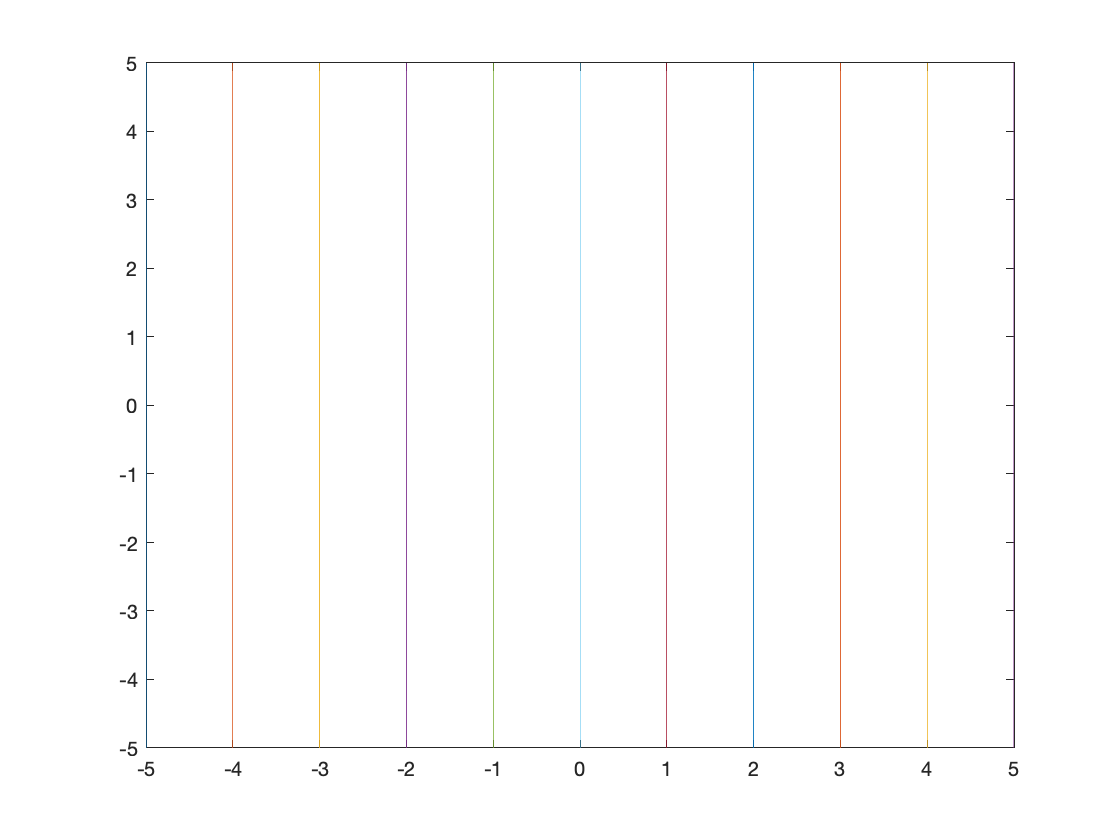

plot(U1,U2)

The command plot(U1',U2') (were are taking the transpose) will plot each row of U2 versus each row of U1.

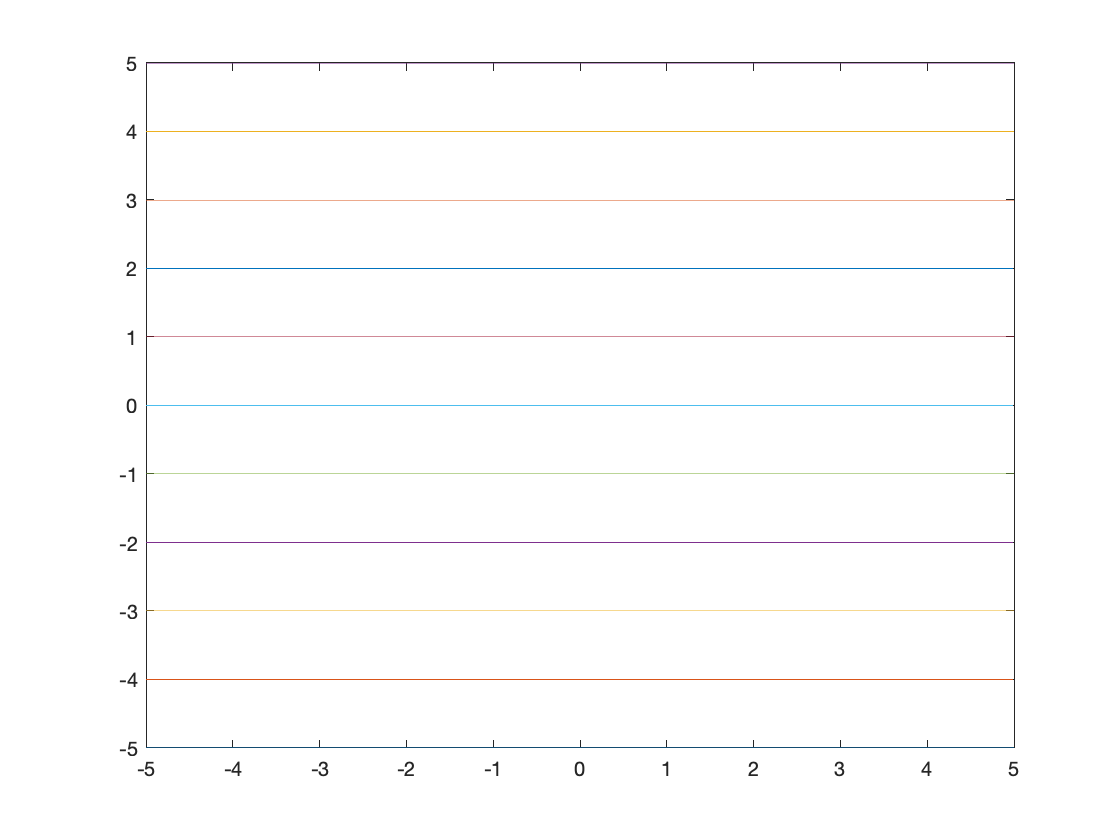

plot(U1',U2')

Now, let's add them both to an image, colored in black.

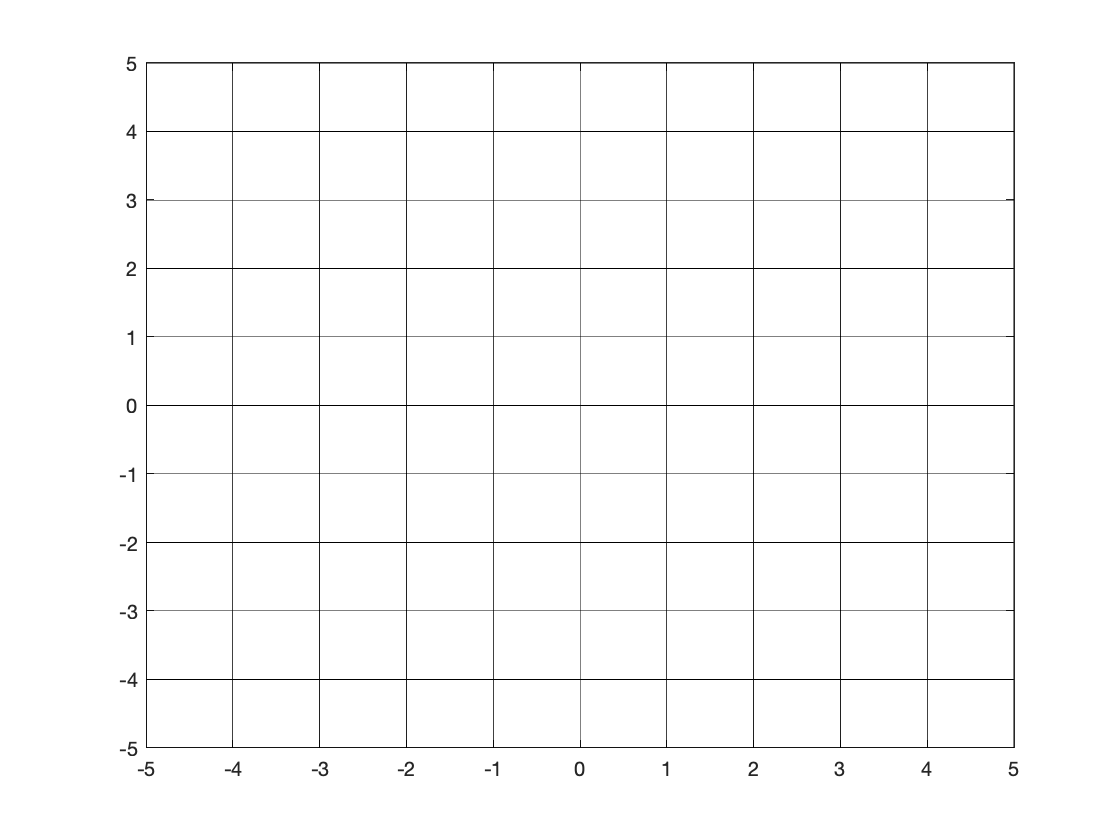

plot(U1,U2,'k',U1',U2','k')
axis([-5,5,-5,5])

Now, let's add the coordinate transform of this image. Recall that


$$\begin{array}{rcl}
x_1&=&u_1-2u_2\\
x_2&=&u_1+u_2
\end{array}$$


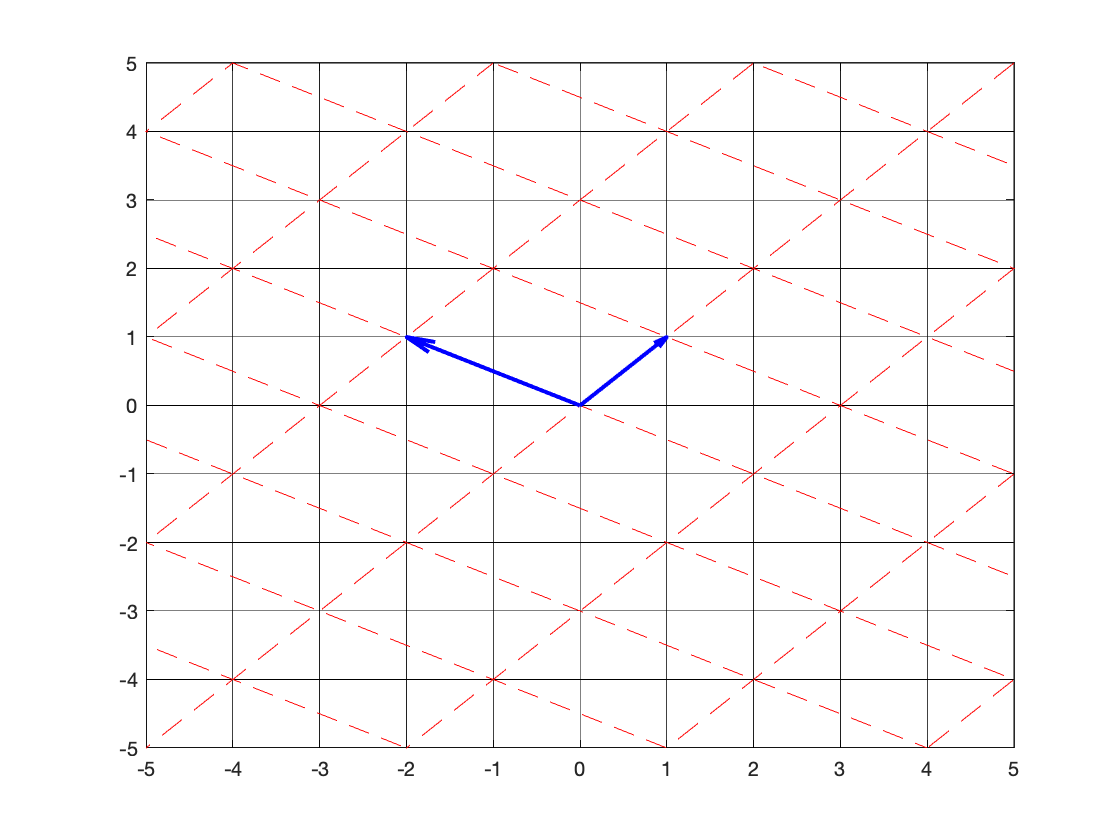

figure
plot(U1,U2,'k',U1',U2','k'),hold on
X1=U1-2*U2;
X2=U1+U2;
axis([-5,5,-5,5])
plot(X1,X2,'r--',X1',X2','r--')
quiver(0,0,1,1,0,'b','LineWidth',2,'MaxHeadSize',0.5)
quiver(0,0,-2,1,0,'b','LineWidth',2,'MaxHeadSize',0.5)
hold off

Again, lines! Not only that, but now we have a nice sheet of graph paper with coordinate systems for both base $E$ and base $B$. :-)